# Training data calculation (static)

yoshimura code をマイナーチェンジ→genTrainStaticFixed_h.mlxをマイナーチェンジ

- 学習データの入力に過去のライトカーブの平均を追加（平均を取る理由は，推定の時には観測ノイズが乗るため1step前の値だけだとあまり意味を持たない．と考えたから．）

衛星の姿勢と，Obs-Sun-Sat の幾何的な関係からライトカーブを回帰するための学習データをとりあえず作る

- light curveの計算では km ではなく，m で計算をすることに注意．

clc
clear

### add path to use functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得

% create directory
mkdir ../../data/static/


tStart = tic;

### clear the data directory

traindatadir = strcat(curdir, '/../../data/static');
cddir = traindatadir;
cd(cddir);
delete *.csv
cd(curdir);

### flags and constants

TLE = 1;
model = 2; % 1: flatplate, 2: boxWing
% nMC = 1; % # of training data
lcModel = 'AS';
% fixed = 'random' % "random" or "tleInit" or ""

const = orbitConst;
earthVSOP = vsopConst;

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

CdCs_mat = [0.9, 0.1
            0.7, 0.3
            0.5, 0.5
            0.3, 0.7
            0.1, 0.9];
% CdCs_mat = [0.7, 0.3
%             0.5, 0.5
%             0.3, 0.7];
CdCs_mat = [0.5, 0.5];

tSpanPast = 20; % odeを解く時間とその平均を取るためのタイムステップ数

nPosition = 5 % 学習する位置の数


## satellite parameter

if model == 1
    objName = 'flatPlate.obj';
    nCompo = 1; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivitiy
    sat.rho = sat.Cd;
elseif model == 2
    objName = 'boxWing.obj';
    nCompo = 3; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([45, 50, 60]); % moment of inertia, kgm^2
    sat.m = 100; % mass, kg
    %   optical parameters at wing (manually...)
    sat.Ca(:,:) = 0.0;
    % sat.Cd(:,:) = 0.7;
    % sat.Cs(:,:) = 0.3;
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivitiy
    % sat.rho = sat.Cd;

else
    error('invalid model flag');
end

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


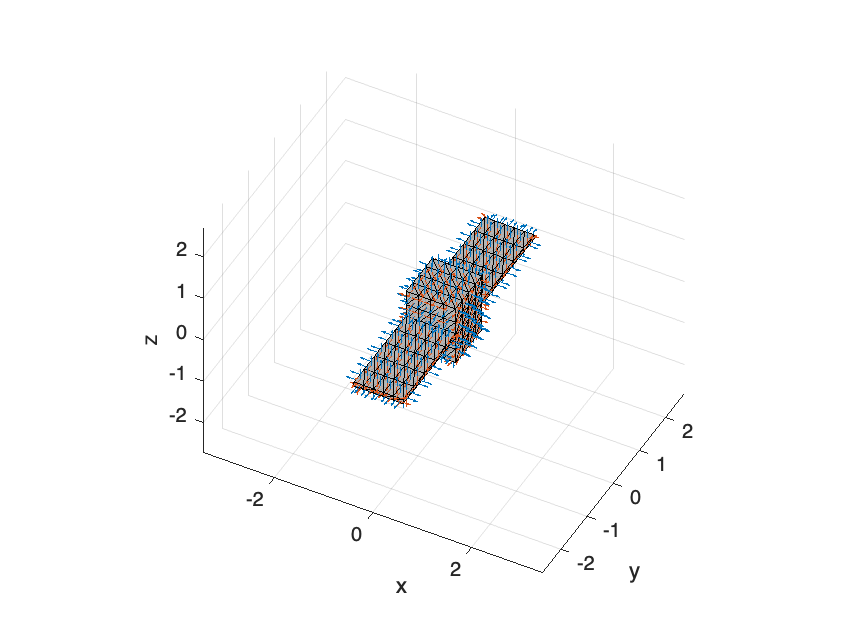

showSC(sat,"Normal","on") % visualize satellite

### initial condition

### attitude of the target

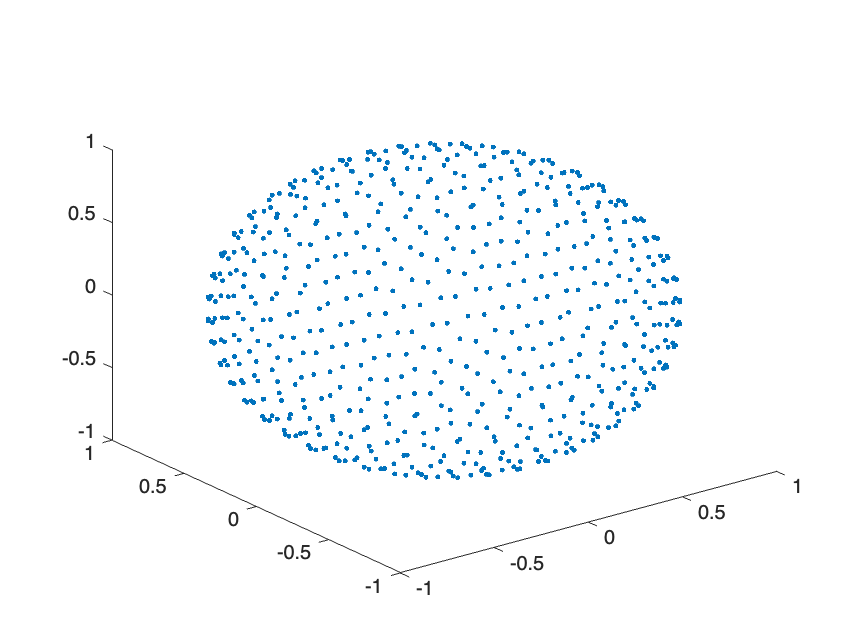

[vv, ~] = icosphere(3);
[azi, ele, ~] = cart2sph(vv(:,1), vv(:,2),vv(:,3));

figure
plot3(cos(azi).*cos(ele), sin(azi).*cos(ele), sin(ele),'.'); % km


psi = 0:deg2rad(60):2*pi;
nPsi = length(psi);

qIni = [];
for i = 1:length(azi) % each azimuth and elevationに対してpsiをふる
    tmp = zyz2q(4, azi(i) .* ones(nPsi,1), (pi/2-ele(i)) .* ones(nPsi,1), psi);
    qIni = [qIni
        tmp];
end

wIni = deg2rad([0.1, -0.1, -0.25]); % とりあえず1パターン

% nTrain = nSun * length(azi) * length(psi)
% patterns_surfaceParameters = size(CdCs_mat, 1)

### orbit

tle.oe = $a {\rm [km]}, e,i {\rm [rad]},\Omega {\rm [rad]},\omega{\rm [rad]},M{\rm [rad]}$

if TLE == 1
    tle = readTLE('JCSAT2_edited.txt', const);
else
    a = 42164.91220781728; % km
    e = 0.000215800000000; % eccentricity
    inc = 0.000938987137573; % rad
    W = 4.918899828139163; % rad
    w = 0.876621287411436; % rad
    m = 1.585708419923936; % rad

    tle.oe = [a e inc W w m];
    tle.jd = 2.458535992836310e+06;
end

[rIni, vIni] = oe2rv(tle.oe, 1, const); % [km, km/s], @ inertial frame
rIni = rIni .* 10^3; % [m]
vIni = vIni .* 10^3; % [m]
jd = tle.jd; % [day], Julian day
[yy, mm, dd, hh, m, s] = jd2gc(jd);
utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)

nIniCon = size(qIni, 1)
rIni = repmat(rIni, nIniCon, 1);
vIni = repmat(vIni, nIniCon, 1);
wIni = repmat(wIni, nIniCon, 1);

xIni = [rIni, vIni, qIni, wIni]; % odeのための初期条件たち

### observer location

obsLon = deg2rad(130.216544); % [rad], longitude
obsLat = deg2rad(33.3594649); % [rad], latitude
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % [km], observer position @ECEF(Earth Centered Earth Fixed)
obsPosECEF = obsPosECEF .* 10^3; % [m], 1x3 vec

dcmITRF2gcrf = itrf2gcrf(utc, leapJD, iau06, eopDataAll);
qITRF2gcrf = dcm2q(4, dcmITRF2gcrf);
qGCRF2itrf = dcm2q(4, dcmITRF2gcrf');
obsECI = qRotation(4, obsPosECEF, qITRF2gcrf); % [m], observer @ECI, 1x3 vec

### satllite & observer & Sun location

とりあえず全ての位置を固定

% rng(1, "twister"); % 乱数の再現性
% 
% % satellite position
% satPos = [0, 0, 0] % sat is origin
% 
% nSun = 1; % 太陽の位置の数
% 
% if strcmp(fixed, "random")
%     % observer position
%     obsPos = [36000, 0, 0] % 高度36000km 
%     obsPos = obsPos .* 10^3; % [m]
% 
%     sunAzi = pi .* rand(nSun, 1) - pi/2;
%     sunEle = acos(1 - 2 .* rand(nSun, 1));
%     sunPos = const.AU .* [cos(sunAzi).*sin(sunEle), sin(sunAzi).*sin(sunEle), cos(sunEle)]  % km
%     sunPos = sunPos .* 10^3; % [m]
% elseif strcmp(fixed, "tleInit")
%     % jdHistory = tle.jd + s2day(t_); % time history in Julian day
%     % jdHistory = tle.jd;
%     % [yy, mm, dd, hh, m, s] = jd2gc(jdHistory);
%     % utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
% 
% 
%     % とりあえずべたうちでscjsat.tleの初期位置と合わせてみる -----------
%     obsPos = [-2.0005, -3.2290, 0.3506] .* 10^4; % [km]
%     obsPos = obsPos .* 10^3; % [m]
%     sunPos = [1.3096, -0.6315, -0.2736] .* 10^8; % [km]
%     sunPos = sunPos .* 10^3; %[m]
% end
% 
% 
% % plot ------
% figure
% plot3(sunPos(:,1)./10^3, sunPos(:,2)./10^3, sunPos(:,3)./10^3,'r*');
% hold on;
% plot3(satPos(:,1)./10^3, satPos(:,2)./10^3, satPos(:,3)./10^3, 'kx');
% hold on;
% plot3(obsPos(:,1)./10^3, obsPos(:,2)./10^3, obsPos(:,3)./10^3, 'bo');
% % tmp = gmst(jdHistory(end));
% % drawEarth(tmp, 0.6, const);
% legend("Sun", "Satellite", "Observer");
% xlabel('x [km]'), ylabel('y [km]'), zlabel('z [km]')
% title("sat-obs-Sun geometirc position");
% axis equal

### generate training data

% satPos = repmat(satPos, nTrain, 1);
% obsPos = repmat(obsPos, nTrain, 1);
% sunPos = repmat(sunPos, nTrain, 1);
% q = repmat(q, nSun, 1);

% preallocations for outputs
mApp_pastMean = zeros(nIniCon, nPosition, size(CdCs_mat, 1));
mApp = zeros(nIniCon, nPosition, size(CdCs_mat, 1));

t_jd = zeros(nIniCon, 1, nPosition, size(CdCs_mat,1));
r = zeros(nIniCon, 3, nPosition, size(CdCs_mat, 1));
v = zeros(nIniCon, 3, nPosition, size(CdCs_mat, 1));
w = zeros(nIniCon, 3, nPosition, size(CdCs_mat, 1));
q = zeros(nIniCon, 4, nPosition, size(CdCs_mat, 1));
obsECI = zeros(nIniCon, 3, nPosition, size(CdCs_mat, 1));
sunPosI = zeros(nIniCon, 3, nPosition, size(CdCs_mat, 1));


tStep = 1;
tSpanEnd = 60*10;
tSpan = 0:tStep:tSpanEnd;

% 真ん中の時刻の姿勢と位置で学習したい
% tPropStart = tSpanEnd/2;
% tPropEnd = tSpanEnd/2+tSpanPast;

% 複数の時刻の姿勢と位置で学習
% nPosition = 5 % 学習する位置の数
tStepPosition = tSpanEnd/nPosition;
for i = 1:1:nPosition
    tPropStart(i,1) = tSpanEnd/nPosition * (i-1);
    tPropEnd(i, 1) = tPropStart(i,1) + tSpanPast;
end




options = odeset('RelTol',1e-9,'AbsTol',1e-9);

for i = 1:1:size(CdCs_mat, 1)
    sat.Cd = CdCs_mat(i,1);
    sat.Cs = CdCs_mat(i,2);
    sat.rho = sat.Cd;
    for j = 1:1:nIniCon
        mApp_tmp = zeros(size(tSpan, 2), 1);

        [t_, x_] = ode89(@(t,x)eomAttiOrb_h(t,x,const,earthVSOP,sat,jd), tSpan, xIni(j,:), options); % torque free
        % data handling (とりあえず全部に _tmp をつけてるけどいらないっちゃいらない?)
        jdHistory_tmp = tle.jd + s2day(t_); % time history in Julian day
        [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
        utc_tmp = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
        for ii = 1:length(t_)
            dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
            qITRF2gcrf_tmp(ii, :) = dcm2q(4, dcmITRF2gcrf_tmp);
        end
        
        r_tmp = x_(:,1:3); % [m], position @ i-frame
        v_tmp = x_(:,4:6); % [m/s], velocity @ i-frame
        q_tmp = x_(:,7:10); % quaternion w.r.t. inertial frame
        w_tmp = x_(:,11:13); % [rad/s], angular rate w.r.t. inertial frame

        % Sun position and Observer positions
        sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
        sunPosI_tmp = sunPosI_tmp .* 10^3; %[m]
        sunRel_tmp = sunPosI_tmp - r_tmp; % [m], relative vec from sat to sun @inertial frame, nx3
        % sunPosB = qRotation(4, normRow(sunRel), q);% sun unit directional vectors @body-fixed frame, nx3
        obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
        obsRel_tmp = obsECI_tmp - r_tmp; % [m], relative vec from sat to observer @inertial frame, nx3
        % obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors @inertial frame, nx3

        % generate lighcurves
        nu = shadow(r_tmp./10^3, sunPosI_tmp./10^3, const.RS, const.RE); % calc Earth's shadow
        [mApp_tmp(:, 1), ~] = lc(sat, 4, q_tmp, r_tmp, obsECI_tmp, sunPosI_tmp, 1, 'AS');

        % 複数の位置に対応する学習データを作成
        for k = 1:1:nPosition
            mApp_pastMean(j,k,i) = mean(mApp_tmp(tPropStart(k,1):(tPropEnd(k,1)-1), 1));
            mApp(j,k,i) = mApp_tmp(tPropEnd(k,1),1); % [nIniCon, patterns of CdCs]
    
            t_jd(j,1,k,i) = jdHistory_tmp(end,1)/nPosition * k; % 姿勢とライトカーブの組み合わせを得られたJulian day
            r(j,:,k,i) = r_tmp(tPropEnd(k,1),:);
            v(j,:,k,i) = v_tmp(tPropEnd(k,1),:);
            q(j,:,k,i) = q_tmp(tPropEnd(k,1),:); % 一応3次元目で表面特性ごとにわけてるけど，たぶん全部ほぼ同じ？
            w(j,:,k,i) = w_tmp(tPropEnd(k,1),:);
            obsECI(j,:,k,i) = obsECI_tmp(tPropEnd(k,1),:);
            sunPosI(j,:,k,i) = sunPosI_tmp(tPropEnd(k,1),:);
        end
    end
        % [mApp(:, i), ~] = lc(sat, 4, q, satPos, obsPos, sunPos, 1, 'AS'); % [nTrain, patterns of CdCs]
end

### save data

savedir = strcat(curdir, '/../../data/static/')

savedir = '/Users/hararyui/Documents/ku/master_research/codes_master/estimation/static_version/../../data/static/'

for i = 1:1:size(mApp, 2)
    fName = strcat('trainStatic', sprintf('%03d', i), '.csv');
    saveName = strcat(savedir, fName);
    writematrix([t_jd(:,1,i), mApp(:,i), q(:,:,i), r(:,:,i), obsECI(:,:,i), sunPosI(:,:,i), mApp_pastMean(:,i)], saveName);
end
% fName = strcat('yTrain', sprintf('%03d', i), '.csv');
% saveName = strcat(savedir, fName);
% writematrix(mApp, saveName);

tEnd = toc(tStart) / 60; % [min]
strcat("calculation time [min] : ", num2str(tEnd))

ans = "calculation time [min] : 81.3339"

confirmation that the error of the orbit are 0

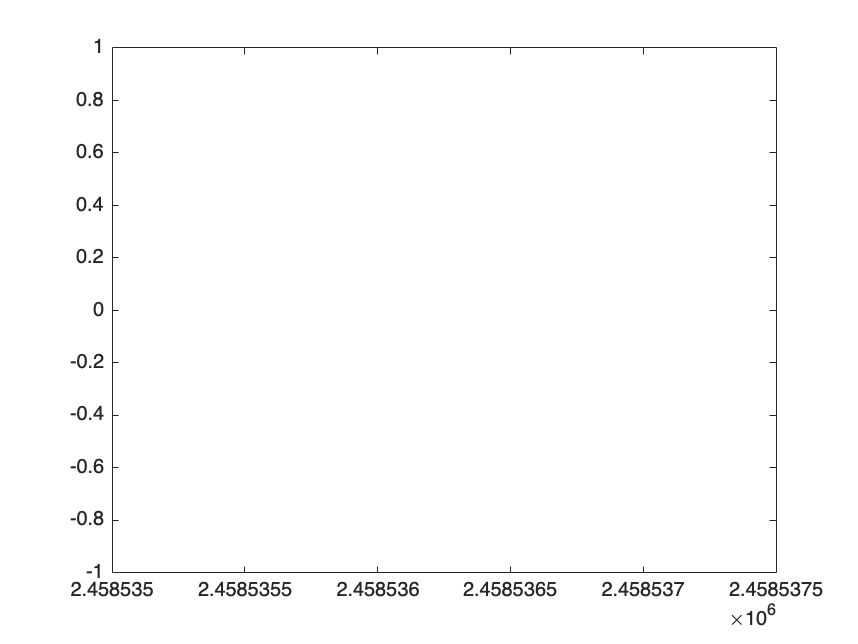

rError = r(:,:,1) - r(:,:,2);
obsECIError = obsECI(:,:,1) - obsECI(:,:,3);
sunPosIError = sunPosI(:,:,1) - sunPosI(:,:,5);

figure; % 何も出ないことが想定通り
plot(t_jd(:,:,1), rError(:,1), '-r');
hold on;
plot(t_jd(:,:,1), rError(:,2), '-r');
hold on;
plot(t_jd(:,:,1), rError(:,3), '-r');
hold on;

plot(t_jd(:,:,1), obsECIError(:,1), 'g-');
hold on;
plot(t_jd(:,:,1), obsECIError(:,2), 'g-');
hold on;
plot(t_jd(:,:,1), obsECIError(:,3), 'g-');
hold on;

plot(t_jd(:,:,1), sunPosIError(:,1), 'b-');
hold on;
plot(t_jd(:,:,1), sunPosIError(:,2), 'b-');
hold on;
plot(t_jd(:,:,1), sunPosIError(:,3), 'b-');
hold off;


% for i = 1:1:3
%     fName = strcat('test', sprintf('%03d', i), '.csv');
%     saveName = strcat(pwd,'/', fName);
%     for k = 1:1:5
%         writematrix([k, k, k, k], saveName);
%     end
% end